# Draw graph of error evaluation vs (λ,η)

 This script draws a graph of estimation error evaluation vs (λ,η)

 The results are load from folder "../results"

 Requirements: MATLAB R2022a

 Copyright (c) 2022, Ruiki KOBAYASHI and Shogo MURAMATSU, All rights reserved.

 Contact address: Shogo MURAMATSU,

    Faculty of Engineering, Niigata University,

    8050 2-no-cho Ikarashi, Nishi-ku,

    Niigata, 950-2181, JAPAN

    [http://msiplab.eng.niigata-u.ac.jp/](http://msiplab.eng.niigata-u.ac.jp/)

iLv = 2;
nSet = 441;
t = "2022-04-13-07-55";
%
filename = "graph-" + num2str(nSet) + "-level-" + num2str(iLv) + "-" + t;
% Load result
S = load("../data/materials/" + filename,...
    'graph','gammas','nSet','nEtaSet','mu','gamma1','config');
graph = S.graph;
nSet = S.nSet;
nEtaSet = S.nEtaSet;
mu = S.mu;
gamma1 = S.gamma1;
gammas = S.gammas;
config = S.config;
% Display results
for iSetting = 1:nSet
    ils = floor((iSetting-1)/nEtaSet)+1;
    ies = mod(iSetting-1,nEtaSet)+1;
    xlambda(ils) = graph(iSetting,2); %#ok<SAGROW> 
    yeta(ies) = graph(iSetting,3); %#ok<SAGROW> 
    zmse(ils,ies) = graph(iSetting,1); %#ok<SAGROW> 
end


hfig = figure;
mesh(yeta,xlambda,zmse,'FaceColor','interp','EdgeColor','none')
xlabel('$\eta$','Interpreter','latex')
ylabel('$\lambda$','Interpreter','latex')
zlabel('MSE')
%     title(['Tree Level'  num2str(i) 'minMSE' num2str(min(graph(:,1)))])
set(gca,'yscale','log','xscale','log','fontsize',12)
colormap('turbo')
%caxis([min(graph(:,1)) max(graph(:,1))])
caxis([6 10]*1e-6)
view(0,90)
colorbar
hold on
[minmse,m ] = min(graph(:,1));
mineta = graph(m,3)

mineta = 0.0126

minlambda = graph(m,2)

minlambda = 0.0025

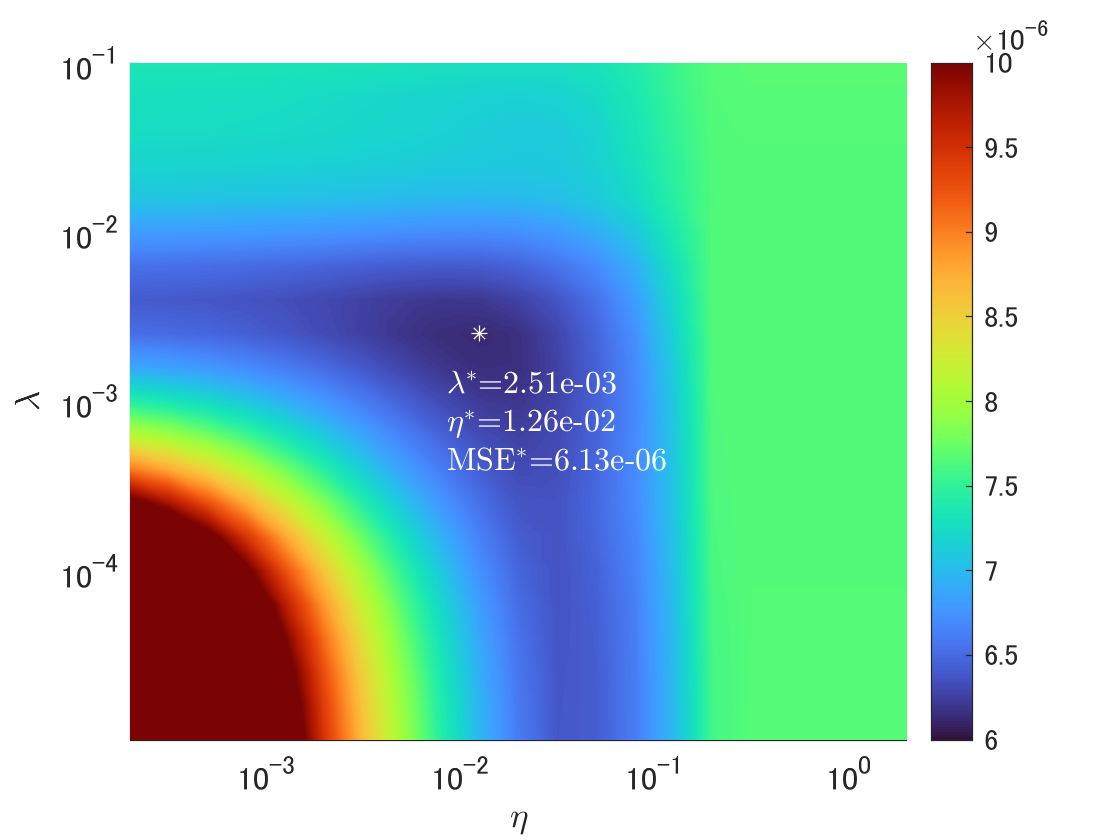

text(graph(m,3)-0.004,graph(m,2)-0.0018,7e-6,...
    "$\lambda^\ast$="+num2str(minlambda,'%0.2e') + newline +...
    "$\eta^\ast$="+num2str(mineta,'%0.2e')+newline+...
    "MSE$^\ast$="+num2str(minmse,'%0.2e'),...
    'Interpreter','latex', 'Color','white','FontSize',12)
plot3(graph(m,3),graph(m,2),1,'*','Color','white')
grid off
axis([min(yeta) max(yeta) min(xlambda) max(xlambda)])
hold off
exportgraphics(hfig,"../results/fig10rev.png",'Resolution',300);

close(hfig)
%saveas(gcf,['../results/graph-' num2str(nSet) '-level-' num2str(iLv) '-' t '.png'])
mu

mu = 6.6651

gammas(:,1)

ans =     0.2858
    0.2858
    0.2858
    0.2858
    0.2858
    0.2858
    0.2858
    0.2858
    0.2858
    0.2858


num2str(gamma1,'%0.2e')

ans = '2.86e-01'

gammas(:,2)

ans =     0.0793
    0.0793
    0.0793
    0.0793
    0.0793
    0.0793
    0.0793
    0.0793
    0.0793
    0.0793


tauSqd = 2;
gamma2 = 1/(1.05*tauSqd)*(1/gamma1-mu/2)

gamma2 = 0.0793

num2str(gamma2,'%0.2e')

ans = '7.93e-02'

config

config = フィールドをもつ struct :
      sigmaw: 0.0500
      pScale: 1
     pSigmaz: 30
     pB4Sinc: 0.0500
       pFreq: 0.3000
    pSigmaxy: 0.5000
     obsSize: [64 64 300]
